# Conversione da tempo continuo a tempo discreto per campionamento: esercizio da prova d'esame

Dato il sistema LTI autonomo, a tempo continuo


$$\dot{x}(t) = A x(t) \qquad A = \left[ \begin{array}{cc}
0 & -1 \\ +1 & 0 \end{array} \right]$$


si vuole determinare la sua descrizione a segnali campionati nei casi seguenti

- periodo di campionamento $\Delta$ pari a: $\Delta = 10$ s;

- periodo di campionamento $\Delta$ pari a: $\Delta = 1/10$ s;

- periodo di campionamento $\Delta$ pari a: $\Delta = 1/2\pi$s ;

Commentare i risultati ottenuti nei tre casi.

NB il periodo di campionamento del caso 3) viene indicato come **periodo di campionamento patologico** (così come la frequenza di campionamento corrispondente viene detta **frequenza di campionamento patologica**).

Che cosa succede nel caso 3) che lo rende tanto particolare rispetto agli altri casi?

`Tratto dalla prova d'esame del 26 settembre 2022`

clear all;
close all;

A = [0 -1; 1 0];
B = [0; 0];
C = [1 0]; % we want to output the state movement
D = 0;

Ts_1 = 10;
Ts_2 = 1/10;
Ts_3 = 1/(2 * pi);

sysC = ss(A, B, C, D);
sysD_1 = c2d(sysC, Ts_1);
sysD_2 = c2d(sysC, Ts_2);
sysD_3= c2d(sysC, Ts_3);

eigC = eig(sysC.A)

eigC =    0.0000 + 1.0000i
   0.0000 - 1.0000i


$T_{s, max} = \pi$ is the maximum sampling time (satisfyig Nyquist's theorem) that we should use. Lower values are fine as well

Ts_1 < pi

ans = logical
   0


Ts_2 < pi

ans = logical
   1


Ts_3 < pi

ans = logical
   1


eigD_1 = eig(sysD_1)

eigD_1 =   -0.8391 + 0.5440i
  -0.8391 - 0.5440i


disp("Module of the eigenvalues: " + abs(eigD_1(1)) + ", " + abs(eigD_1(2)))

Module of the eigenvalues: 1, 1


eigD_2 = eig(sysD_2)

eigD_2 =    0.9950 + 0.0998i
   0.9950 - 0.0998i


disp("Module of the eigenvalues: " + abs(eigD_2(1)) + ", " + abs(eigD_2(2)))

Module of the eigenvalues: 1, 1


eigD_3 = eig(sysD_3)

eigD_3 =    0.9874 + 0.1585i
   0.9874 - 0.1585i


disp("Module of the eigenvalues: " + abs(eigD_3(1)) + ", " + abs(eigD_3(2)))

Module of the eigenvalues: 1, 1


t_fin = 20;

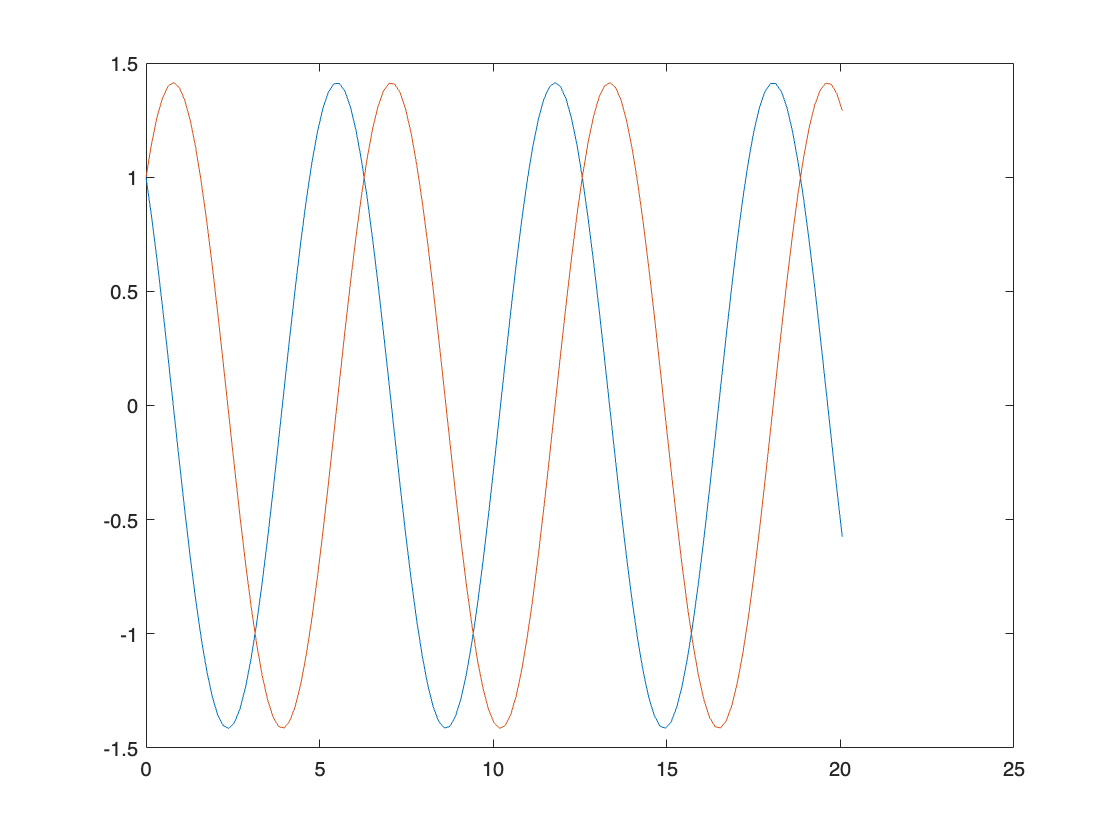

[~, t, x] = initial(sysD_3, [1 1]', t_fin);
plot(t,x)

[~, t, x] = initial(sysD_3, [1 1]', t_fin);
plot(t,x)

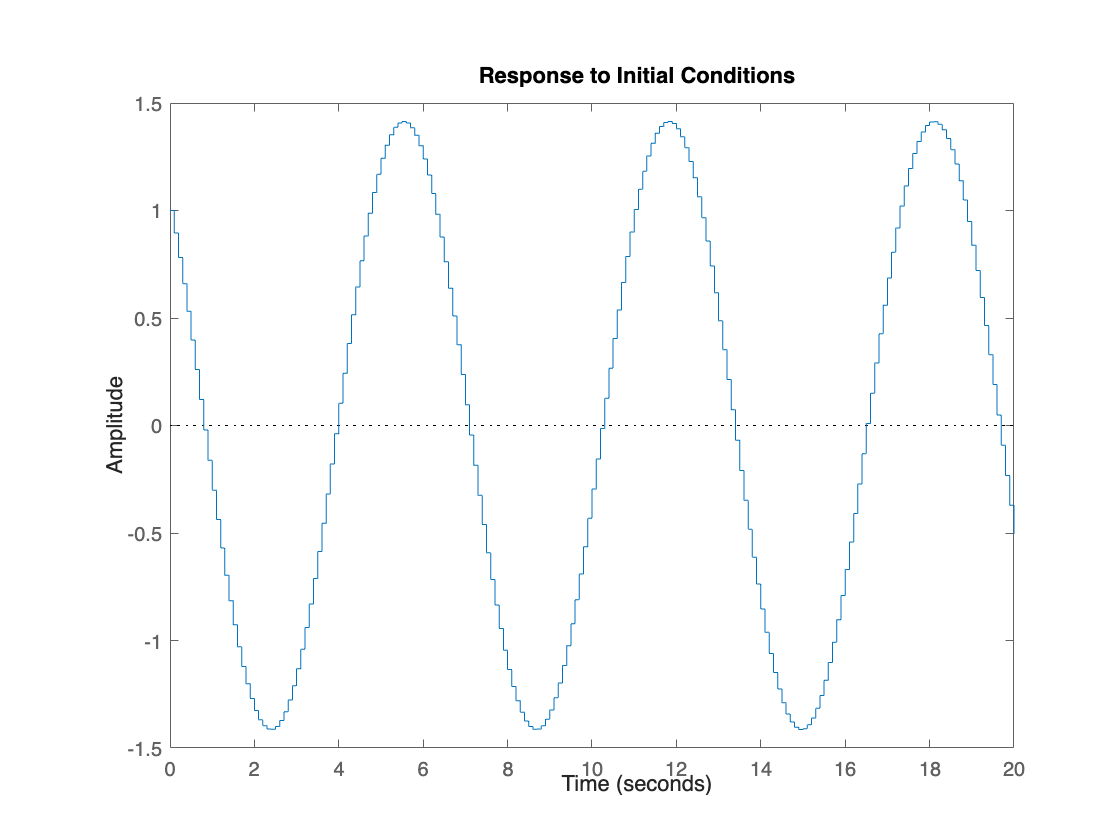

initial(sysD_2, [1 1]', t_fin)

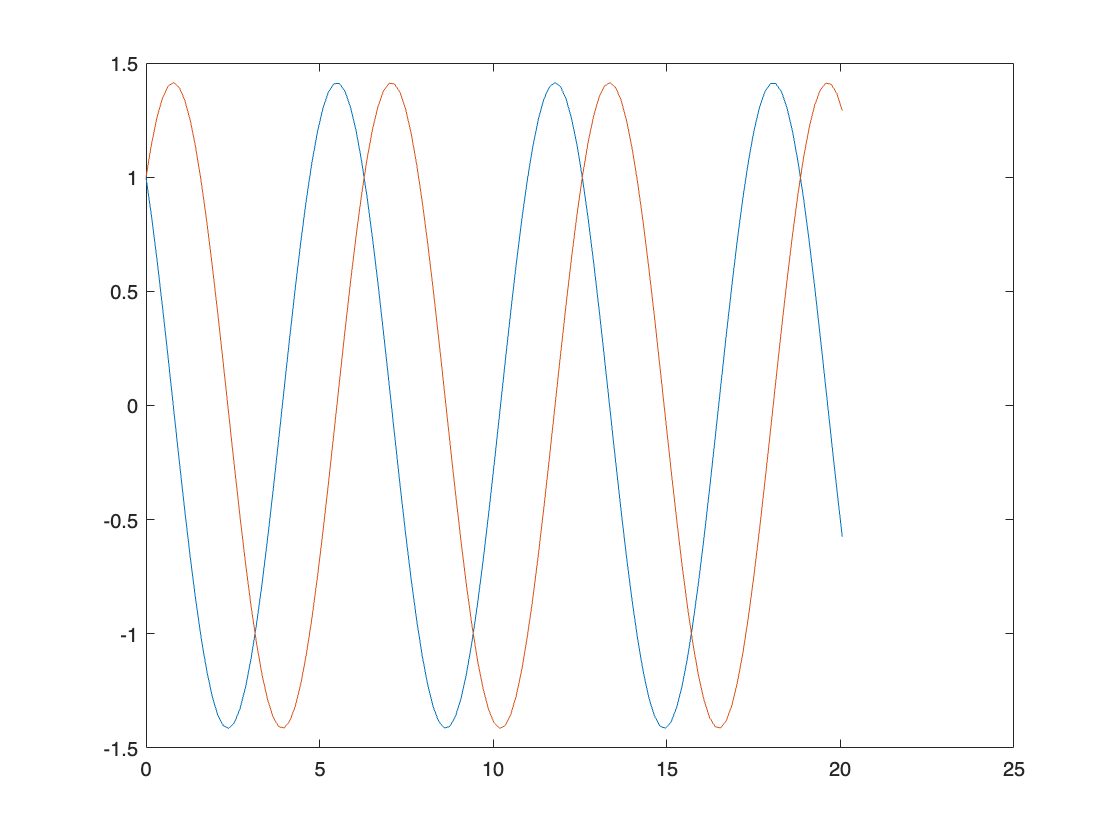

[~, t, x] = initial(sysD_3, [1 1]', t_fin);
plot(t,x)

sysD_4 = c2d(sysC, 2*pi);
eigD_4 = eig(sysD_4)

eigD_4 =    1.0000 + 0.0000i
   1.0000 - 0.0000i


disp("Module of the eigenvalues: " + abs(eigD_4(1)) + ", " + abs(eigD_4(2)))

Module of the eigenvalues: 1, 1


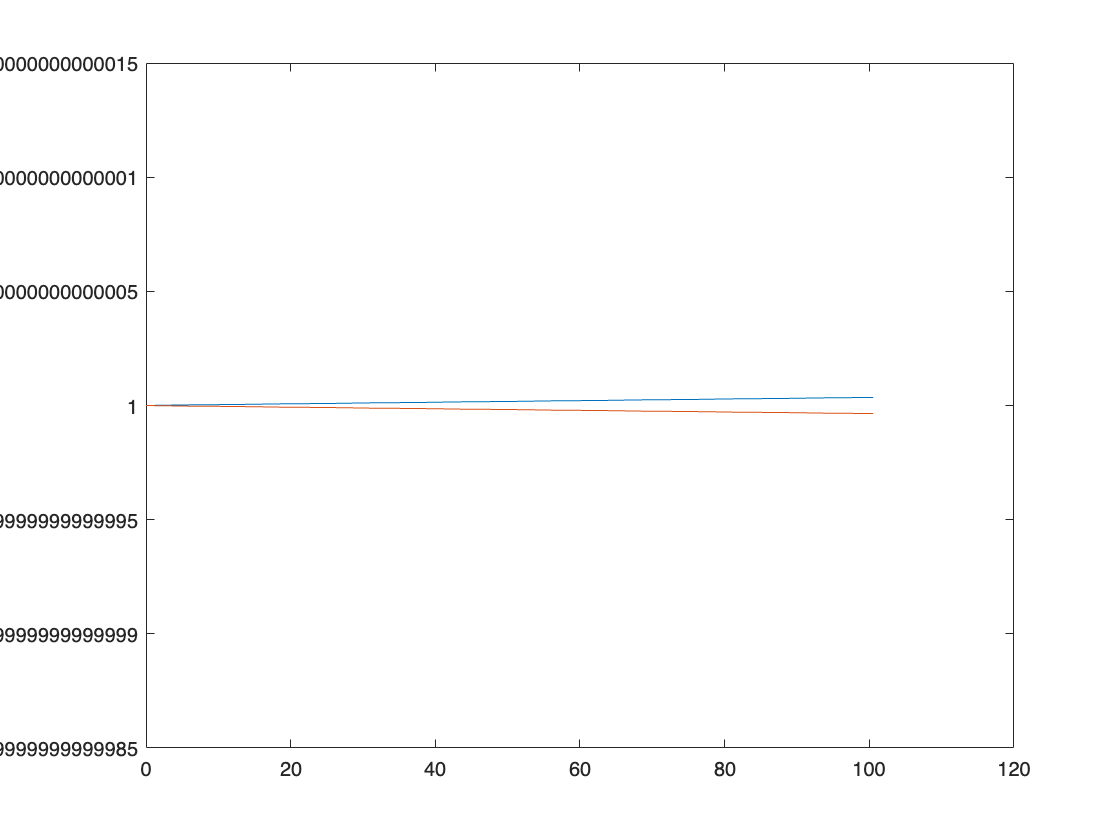

[y, t, x] = initial(sysD_4, [1 1]', [0 100]);
plot(t,x)

Having a look at the eigenvalues of the system, we can determine the resonating frequency as $\frac{1}{2 \pi} = 0.159 Hz \Rightarrow T_s = 6.2832s$, thus we need sampling frequencis at least twice as high. 

In the 4th case, where we are using $T_s  = 2 \pi$, we get real eigenvalues, which are totally wrong compared to what we should expect: complex eigenvalues since the system is an oscillator.

Patological case because it's $k T_{s,max}$, so $k$ times the minimum time.